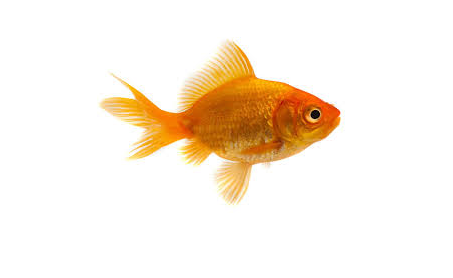

I = imread("Fish_Image\Goldfish-1.jpg");
IG = rgb2gray(I);
[Features, hogVisualisation] = extractHOGFeatures(IG);
figure; imshow (I);

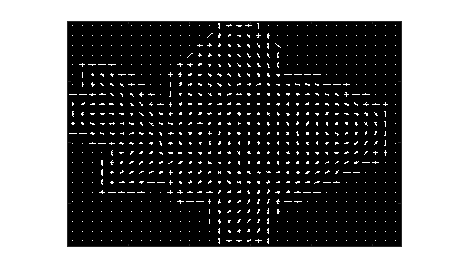

plot(hogVisualisation);

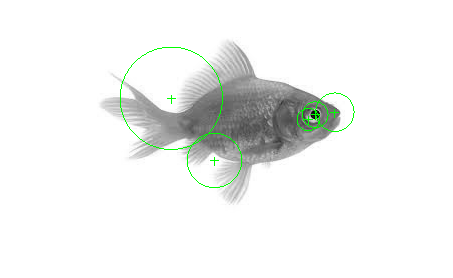

Ipts = detectSURFFeatures(IG);
[Iref_features,  Iref_validPts] = extractFeatures(IG,  Ipts);
figure; imshow(IG); hold on;
plot(Ipts.selectStrongest(5));